# Pedestal analysis for each channel and ASIC

% clear; clc;

main_folder = 'aggregated_pedestal/';
N = 300

N = 300


if (~exist(main_folder,'dir'))
    mkdir(main_folder);
end

i = 20

i = 20

j = 2

j = 2

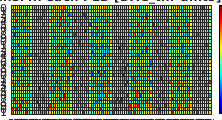

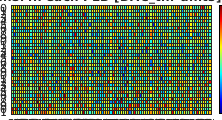

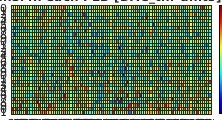

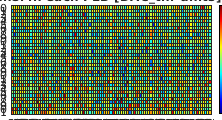

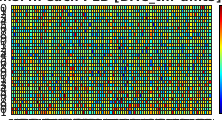


pedestal = NaN(32*8,N);
for i=0:N-1
    number = sprintf('%03i',i);
    if (exist(['FEB_Test/MODULE_',number,'/1/data/Pedestals.dat']))
        data = importdata(sprintf('FEB_Test/MODULE_%03i/1/data/Pedestals.dat',i));
        pedestal(:,i+1) = cell2mat(cellfun(@str2num,data.textdata(2:end,3),'un',0));
    end
end

% remove invalid FEBs
plot_pedestal = pedestal(:,~isnan(pedestal(1,:)));
asic_n = 0:1:N-1;
plot_asic_n = asic_n(~isnan(pedestal(1,:)));

for j=0:7
    figure('units','normalized','outerposition',[0 0 .9 .9])
    subaxis(1,1,1,'Padding', 0.04, 'Margin', 0.01);
    heatmap(plot_pedestal(j+1:8:end,:),'XDisplayLabels',plot_asic_n,'YDisplayLabels',0:1:31);
    colormap('jet');
    xlabel('#FEB');
    ylabel('#Channel');
    caxis([70, 230])
    title(sprintf('Pedestal for each channel in each FEB [DAC\\_thr units]. Peaking time = tau\\_%i',j));
    saveas(gcf,sprintf([main_folder, 'Pedestal_tau%i.svg'],j));
    
    temp = pedestal(j+1:8:end,:);
    file_out = sprintf([main_folder, 'Pedestal_tau%i.dat'],j);
    
    fileID = fopen(file_out,'w');
    fprintf(fileID,'#---------------------------------------------------------\n');
    fprintf(fileID,'# Pedestal for each channel in each ASIC [DAC_thr units]. Peaking time = %i\n',j);
    fprintf(fileID,'# Rows: #Channels\n');
    fprintf(fileID,'# Columns: #FEB\n');
    fprintf(fileID,'#---------------------------------------------------------\n');
    s = repmat('%2.3f\t',1,N);
    s(end+1:end+2) = '\n';
    fprintf(fileID,s,temp');
    fclose(fileID);
end